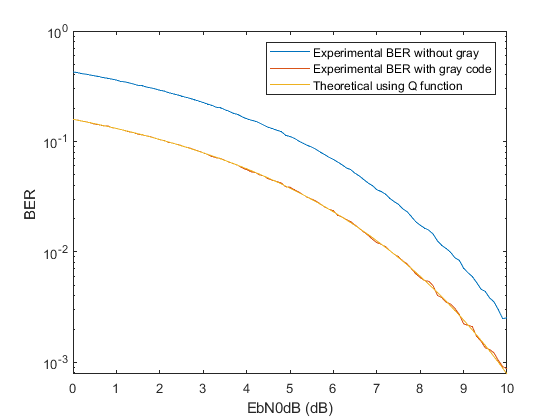

%Demonstration of QPSK modulation and Demodulation with gray labling and without gray labeling.

%We take the input signal as -1 everytime to make implementation a little
%faster. We then add the AWGN with unit mean and compare it with constellation.
%closer to 1 we have a bit error and count all such errors for all values of
%SNR. We have taken 10^5 and 10^6 bits of signal in this experiment.
%We have not used any modules to hope for faster implementation of code.

%First of all we clear all existing data.
clc;
clear all;
close all;

%generate QPSK constellation as complex numbers
k=double(1.0)/double(sqrt(2)); %The normalizing factor
constellation=k*[1+1i -1+1i -1-1i 1-1i]; %To store constellation points ie. 1+1j , 1-1j ,  -1-1j , -1+1j in complex double
gre=[0 1 3 2]; %This is used to map between non - gray and gray constellation points.
%number of symbols in simulation

%———Input Fields————————
nsymbols = 200000; %  represents number of symbols used for stimulation. ie 10^5.

%Generating nsymbols random 2 bit symbols to use for DQPSK
input=zeros(1,nsymbols);
for k=1:nsymbols %Loop to generate 2 bit random inputs symbols.
 input(k)= randi([0, (2^2-1)]); %randomly generates a 2 bit number between 0 and 3 including both of them.
end
EbN0dB = 0:0.1:10; % multiple Eb/N0 values from 0-10 dB 
inputc=constellation(input(:)+1); %will have the constellation symbols for non gray
input_gray=gre(input(:)+1);%will get the corresponding gray input for the same constellation input.
inputc=inputc.'; %Taking non conjugate transpose of input signal

number_EbN0dBs = length(EbN0dB); %Number of EbN0dB values to check
perr_estimate = zeros(number_EbN0dBs,1); %To estimate error for each EbN0dB value and add it to estimate
perr_estimate_gray = zeros(number_EbN0dBs,1); %To estimate error for each EbN0dB value and add it to estimate for Gray code

for k=1:number_EbN0dBs %EbN0dB for loop
    EbN0dB_now = EbN0dB(k); %The current value of EbN0dB being tested for BER.
    ebno=10^(EbN0dB_now/10); %We convert EbN0dB from dB to decimal unit.
    sigma=sqrt(1/(2*ebno)); %The corresponding varience for noise.
    
    % add 2d Gaussian noise to our symbols.
    received = inputc +sigma*randn(nsymbols,1)+1i*sigma*randn(nsymbols,1); %For adding WNGN
    decisions=zeros(nsymbols,1); %We initialize decisions with zeros corresponding to all n symbols for fast execution.
    for n=1:nsymbols         
        distances = abs(received(n)-constellation);%Absolute distance from each constellation point.
        [min_dist,decisions(n)] = min(distances); %The minimum of those is choosen for that recieved point.
    end
    decisions_gray=gre(decisions);%Maps back non gray to gray
    decisions=decisions-1;%To get it between 0 and 3.
    
    %To calculate bit errors here, for faster execution.
    num=zeros(nsymbols,1);
    for s=1:nsymbols
        d_bin=de2bi(decisions(s),2); %To get a zero padded 2 bit binary string for ease of comparing.
        i_bin=de2bi(input(s),2);  %To get a zero padded 2 bit binary string for ease of comparing.
        biterror=0;   %To count error per bit    
        for t=1:2
            if d_bin(t)~=i_bin(t)
                biterror=biterror+1;  %adding error for each incorrectly decieded bit.
            end
            num(s)=biterror; %To store the total bit error for each word 
        end
    end
    error= num;
    
    num_gray=zeros(nsymbols,1);
    %For gray encoded
    for s=1:nsymbols
        d_gray=de2bi(decisions_gray(s),2); %To get a zero padded 2 bit binary string for ease of comparing.
        i_bin=de2bi(input_gray(s),2);  %To get a zero padded 2 bit binary string for ease of comparing.
        biterror=0;   %To count error per bit
        for t=1:2
            if d_gray~=i_bin(t)
                biterror=biterror+1;  %adding error for each incorrectly decieded bit.
            end
            num_gray(s)=biterror; %To store the total bit error for each word 
        end
    end
    errors_gray= num_gray; 
    
    %BER calculations for that snr.
    perr_estimate(k) =perr_estimate(k)+ sum(error)/(nsymbols); %This gives BER per symbol.
    perr_estimate_gray(k) =perr_estimate_gray(k)+ sum(errors_gray)/(nsymbols); %This gives BER per symbol. as we are adding error for each of the 4 symbols
end
semilogy(EbN0dB,perr_estimate); %To plot the BER per nsymbols with EbN0dB.
hold on; %To add both data in the same plot
semilogy(EbN0dB,perr_estimate_gray); %To plot the BER per nsymbols with EbN0dB.
hold on;
semilogy(EbN0dB,qfunc((sqrt(10.^(EbN0dB/10))))); % To plot BER theoretical using Q-function .
legend("Experimental BER without gray ","Experimental BER with gray code","Theoretical using Q function"); %To all legend
xlabel("EbN0dB (dB)"); %To add EbN0dB label to x axis
ylabel("BER "); %To add BER label to y axis. its BER per symbol.